# Determine Is from fit of the V(I)

clearvars; close all
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\IV curve chip\01_IV_curve_chip_spento.txt';

CONVERSION = 20e3;
if endsWith(LPath, '.lvm')  % Dataset recorded in UTZ
    ivdata = importdata(LPath, '\t', 22);
    V = ivdata.data(:,2);
    I = ivdata.data(:,3);   %- 1e-7;
elseif endsWith(LPath, '.txt')  % Dataset recorded at SuSi building 12.8
    ivdata = importdata(LPath, '\t', 1);
    Vraw = ivdata.data(:,1);
    Iraw = ivdata.data(:,2)/CONVERSION;   
end
Iraw = Iraw + abs(Iraw(Vraw == 0));
Iraw(Vraw == 0)

ans = 0

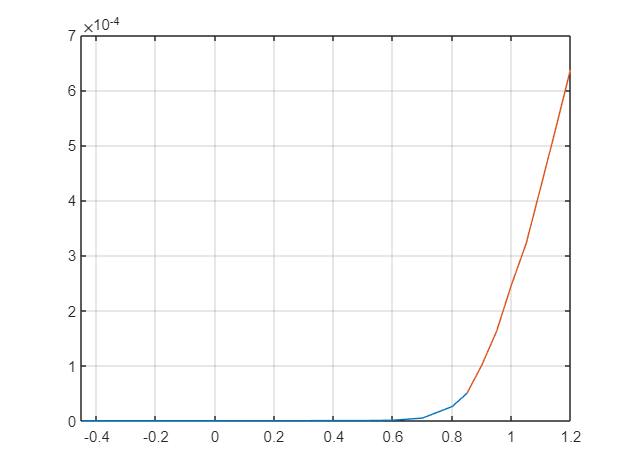

start = 7;
V = Vraw(start:end);
I = abs(Iraw(start:end));

% Plot
figure()
plot(Vraw, Iraw, V, I)
xlim([min(Vraw) max(Vraw)])
grid()

TEMPERATURE = 300;
THERMAL_VOLTAGE_RT = 0.02585;

Rs0 = 350;
alpha0 = 18;
% Is0 = 1e-12;
Is0 = 1.3;
p0 = [Rs0, alpha0];
% T0 = 300/(alpha0*0.02585*2);
n0 = 1/(alpha0*THERMAL_VOLTAGE_RT)

n0 = 2.1492

T = 300/(alpha0*THERMAL_VOLTAGE_RT*n0)

T = 300

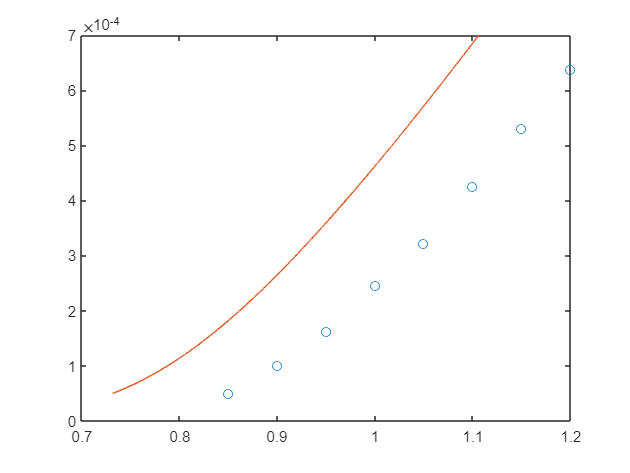

% C(1) = Rs, C(2) = 1/alpha, C(3) = 1/Is
Vmodel = @(I, C, Is) C(1)*I + 1/C(2)*log(I/(Is*1e-10) + 1);

II = linspace(Iraw(start), 7e-4, 10000);
figure()
plot(V, I, 'o')
hold on
plot(Vmodel(II, p0, Is0), II)

OptFit = optimset('display', 'off');
IsFit = lsqnonlin(@(p) V - Vmodell(V, I, p), Is0, [], [], OptFit)

IsFit = 0.0252

[yfit, p] = Vmodell(V, I, IsFit);
p

p =   385.4641   20.2601


n = 1/(THERMAL_VOLTAGE_RT*p(2))

n = 1.9094

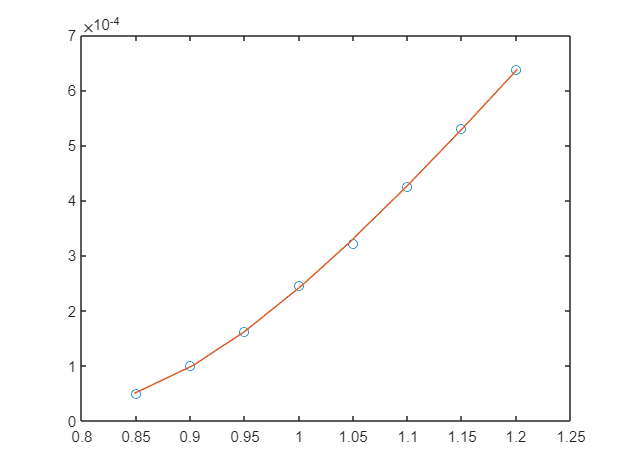

figure()
plot(V, I, 'o')
hold on
plot(yfit, I)

function [Vfit, C] = Vmodell(V, I, Is)

VfitLog = log(I/(Is*1e-10) + 1);
XX = [I, VfitLog];
params = XX \ V;
C(1) = params(1); C(2) = 1/params(2);
Vfit = XX * params;
end